%Formulas NASA
PhiP = 0.1:0.1:1;
PhiR = 1:0.1:10;
Q=802.366;
Tr=298;
Tp=300;

%Metano y O2

%Mezcla pobre
for i=1:1:10
    
    fo2p=1*h('CO2',Tp)+2*h('H2O',Tp)+2*(1-PhiP)./PhiP.*h('O2',Tp)-h('CH4',Tr)-2./PhiP.*h('O2',Tr);
    f1o2p=Cp('CO2',Tp)+2*Cp('H2O',Tp)+2*(1-PhiP)./PhiP.*Cp('O2',Tp);
    Tp=Tp-fo2p./f1o2p;
end
DTPO2 = Tp-Tr;
semilogx(PhiP,DTPO2,'b'); % igual que el plot pero para poner el eje x en escala logaritmica
hold on;
    
%Mezcla rica
Tp=300;
for i=1:1:10
    fo2r=1*h('CO2',Tp)+2*h('H2O',Tp)+(PhiR-1).*h('CH4',Tp)-PhiR.*h('CH4',Tr)-2*h('O2',Tr);
    f1o2r=1*Cp('CO2',Tp)+2*Cp('H2O',Tp)+(PhiR-1).*Cp('CH4',Tp);
    Tp=Tp-fo2r./f1o2r;
end
DTRO2 = Tp-Tr;
semilogx(PhiR,DTRO2,'r');

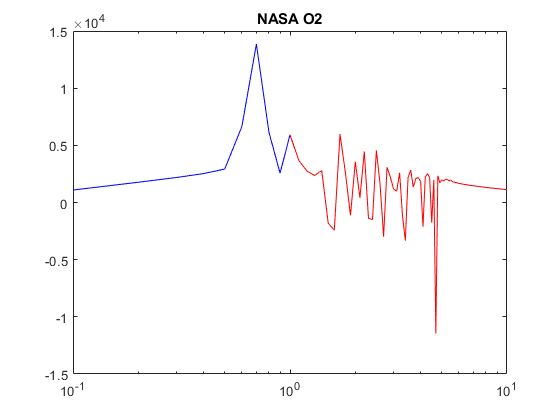

hold off
title("NASA O2")

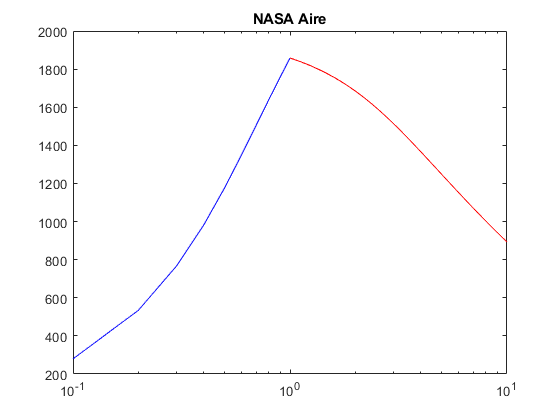

%Metano y aire
PhiP = 0.1:0.1:1;
PhiR = 1:0.1:10;
Q=802.366;
Tr=298;
Tp=300;
%Mezcla pobre
for i=1:1:10
    fn2p=1*h('CO2',Tp)+2*h('H2O',Tp)+2*(1-PhiP)./PhiP.*h('O2',Tp)+7.52./PhiP.*h('N2',Tp)-h('CH4',Tr)-2./PhiP.*(h('O2',Tr)+3.76.*h('N2',Tr));
    f1n2p=Cp('CO2',Tp)+2*Cp('H2O',Tp)+2*(1-PhiP)./PhiP.*Cp('O2',Tp)+7.52./PhiP.*Cp('N2',Tp);
    Tp=Tp-fn2p./f1n2p;
end
DTPN2 = Tp-Tr;
semilogx(PhiP,DTPN2,'b'); % igual que el plot pero para poner el eje x en escala logaritmica
hold on;
    
%Mezcla rica
Tp=300;
for i=1:1:10
    fn2r=1*h('CO2',Tp)+2*h('H2O',Tp)+(PhiR-1).*h('CH4',Tp)+7.52*h('N2',Tp)-PhiR.*h('CH4',Tr)-2*(h('O2',Tr)+h('N2',Tr));
    f1n2r=1*Cp('CO2',Tp)+2*Cp('H2O',Tp)+(PhiR-1).*Cp('CH4',Tp)+7.52*Cp('N2',Tp);
    Tp=Tp-fn2r./f1n2r;
end
DTRN2 = Tp-Tr;
semilogx(PhiR,DTRN2,'r');
hold off
title("NASA Aire")